**EAS 4610 **

**Emily Tribby and Sophia Sparks **

**Introduction: **

Models of the thermal structure of lakes play an important role in more complex lake models as well as provide. 

Numerical Method: FTCS Method 

    Foward Euler in Time 

    Centered Difference in Space 

Time Scale: 1 year (2022-2023) 

Cd = Constant (0.01) 

clear 
%constants 
A=[323343600, 210124300, 52497200, 6732487, 345632];%area in m^2 for depths 1m-4m 
Cw=4.18/1E-6;  %volumetric heat capacity (J*m^3*degC^-1
Beta=0.4; %proportion of shortwave radiation that is absorbed in the surface layer (40%)
n=1.2; %light extiction coefficient for water (m^-1) 
theta=deg2rad(47.3371); %latitude (deg N) 
sig= 5.67E-8; %stepfan boltzman constant (W/m^2K^4) 
td= 86400; %number of seconds in a day
km=2.0204*1E-9*td;  %molecular diffusion of water (m^2d^-1) 
A1= 0.3; %longwave albedo of the lake surface 
Rmw=0.622; %ratio molecular weight of water vapor/dry air = 0.622.
lambda= 2.45; %latent heat of water vaporization, [MJ kg−1]
Cp= 1.005/1000; %specific heat of air at contsant pressure (MJ/kg*K)
k= 0.4; %Von Karmon's constant 
P0= 1;%P0 is the neutral value of the turbulent Prandtl number 
Akm=323.3; %surface area of lake (km^2) 
N= 0.029*Akm^-0.05; %N empiracally determined mass transfer coefficient (mm s m^-1 kPa^-1) (26)
g=9.8; %m/s^2 acceleration due to gravity 
esp= 0.97; % emissivity
rhoe=1; %density of the evaporated water vapor

%Load Yearly Met data from usgs 
data= readmatrix("met_data_2022.csv");
data(:,1)=[];
Ta=data(:,1); %temperature dry bulb (deg C)
Tw=data(:,2); %temperature wet bulb (deg C)
U2= data(:,3)/2.237; %windspeed in mph-> meters/s
for 
C=data(:,4);% cloud coverage (in tenths) 
Kd= data(:,5)/3832; %Solar irradiance data (watt hour /m^2/day )CONVERT TO W/m^2)
P=data(:,6); %pressure kpa

%preallocation 
I=linspace(1,365,365); % julian day 
t= I; %time in julian days 
dz = 1;%meters 
dt = 1; %days 

z=0:dz:4; %depth in meters 
nt=length(t);
nz=length(z);
T=nan.*ones(nz,nt);
Tbound=nan.*ones(nz-2,nt);
S=nan.*ones(nz,nt);
phi = nan.*ones(1,nt);
K = nan.*ones(nz,1);

%set "source" term 
for i = 1: width(S)
    S(:,i)= 1./(A*Cw);
end 
S(1,1) = 0; 
S;
%set surface boundary condition 
for i= 1: nt
    Tbound(1,i)=surftemp(I(i));%neuman boundary aprroximated by cubic spline interpolation of observed data
end 

%set bottom boundary 
Tbound(end, :)= Tbound(1,1)+2; %sufficiently turbid such that it can be assumed to be insulated at bottom 
%set intial condition (T0 for all z)
T(1,:)=Tbound(1,:);  
T(end,1)= Tbound(end,1); 
T(2:end-1,1)= Tbound(1,1)+0.5; %assume polymicitic lake thus little mixing

for i=1:nt-1
%dependant on U2, I, Ta, Tw,C
Ts=surftemp(I(i));
a= 0.02 + 0.01*(0.5-C(i))*(1-sin(pi*(I(i)-81)/183));%parameter that depends on cloud cover an djulian day (13)
deltadeg=-23.4*cos(360*(I(i) + 10)/365);
delta=deg2rad(deltadeg);%solar declination determined by Oke, 1987 (15)
cos_H=-tan(theta)*tan(delta);
H=acos(cos_H);%half-day length (units?) (14)  
b = a + sin(theta)*sin(delta); %(17)
c=cos(theta)*cos(delta);%(18)
B= ((b-c)/(b+c))*tan(pi*H/(2*td))^2; % (19)

if ((b^2) -(c^2)) > 0 %16
    F= 2*(b^2-c^2)^(-1/2)*atan(sqrt(B)); %integration factor 
else 
    F= (-b+c^2)^(-1/2)*log((1+sqrt(-B)/(1-sqrt(-B))));%for b^2-c^2 <0; (16)
end 
As= (a*td/2*H*pi)*F;  %shortwave albedo of the water surface (12)
Ks= Kd(i)*(1-As);%is the net shortwave radiation at the water surface (W/m^2) (11) 

ws= 1.2E-3*U2(i)%w* is the surface value of the friction velocity (m s-) (6)
ks=  6.6*(sin(theta))^(1/2)*U2(i)^-1.84 % a  latitudinally dependent parameter of the Ekman profile, (7) 
Tk = Ts+273;%temperature of surface in kelvin 
rhof= (1-1.9549E-5*abs(Tk-277)^1.68)*10^3; %density of fresh water (kg/m^3)
Nbv= 0.002;%sqrt(-g/(rhof*(dp/dp/dz)));%brunt-vaisala frequency N 

tk= 1-(375.15/(Ts+273));%ambient vapor pressure of the air (27) 
tk2= 1-(375.15/(Tw(i)+273));
e0= 101.325*exp(13.3185*tk -1.9760*tk^2 -0.6445*tk^3 -0.1299*tk^4); % saturation vapor pressure at the lake surface 
eas=101.325*exp(13.3185*tk2 -1.9760*tk2^2 -0.6445*tk2^3 -0.1299*tk2^4);
gamma=(Cp*P(i))/(lambda*Rmw); %psychometric constant (kPa degC ^-1) 
ea = eas - gamma*(Ta(i)-Tw(i)); % ambient vapor pressure of the air

if (1-C(i)) > 0.4 || (1-C(i)) == 0.4
    esp_a= 0.84 - (0.1-9.973E-6*ea)*(1-C(i)) + 3.491E-5*ea; % (21) emissivity of the atmosphere
else 
    esp_a= 0.87 -(0.175 -29.92E-6*ea)*(1-C(i)) + 2.693e-5*ea; %(22)
end 
Ld= esp_a*sig*(Ta(i) +273)^4; % (20) 
Lds= (1-A1)*Ld; %long wave radiation from the atmosphere (23)
Lu= esp*sig*(Ts+273)^3 ;%stefan boltzman law (24) longwave rad from lake surface 
Le=1.91846E6*((Ts +273)/(Ts +329.09))^2; %latent hear fo vaporization (MJ kg^-1) 
E= N*U2(i)*(e0-ea); %evaporation (mm) 
Qe= rhoe*Le*E*(277.7778/1000)*24; %(29) rho is density of the evaporated water vapor (= 1kg m^-3) and Le is the latent heat of vaporization (MJ kg^-1) 
R= gamma*(Ts-Ta(i))*(e0-ea); %bowen ratio R
Qh= R*Qe; % flux of sensible heat (31)


    for m=2:nz
        i;
        Ri= (-1 + sqrt(1+ (40*Nbv^2*(k^2)*(z(m)^2))/ ws^2*exp(-2*k*z(m))))/20; %richardson number 
        K(m) = km + eddy_dif(z(m),k,ws,ks,Ri,P0);
        Cd = K(m)*dt/dz^2;
        phi(i)= (1-Beta)*Ks*exp(-n*z(m)); % heat source term in (W/m^2) Beer's Law (2)
        S(m,i) = S(m,i)*phi(i)*((A(m-1)-A(m))/dz);
        T(m,i+1) = T(m,i) + Cd*(T(m,i)-T(m-1,i)-2*T(m,i)+T(m-1,i)) + S(m,i);
        T(end,:) = T(end,1);
    end 


end

i = 1

ws = 0.0059

ks = 0.3020

i = 2

ws = 0.0038

ks = 0.6937

i = 3

ws = 0.0016

ks = 3.2982

i = 4

ws = 0.0016

ks = 3.2982

i = 5

ws = 0

ks = Inf

i = 6

ws = 0

ks = Inf

i = 7

ws = 0.0038

ks = 0.6937

i = 8

ws = 0.0032

ks = 0.9213

i = 9

ws = 0.0027

ks = 1.2885

i = 10

ws = 0.0043

ks = 0.5426

i = 11

ws = 0.0016

ks = 3.2982

i = 12

ws = 0.0032

ks = 0.9213

i = 13

ws = 0.0032

ks = 0.9213

i = 14

ws = 0.0038

ks = 0.6937

i = 15

ws = 0.0032

ks = 0.9213

i = 16

ws = 0

ks = Inf

i = 17

ws = 0

ks = Inf

i = 18

ws = 0

ks = Inf

i = 19

ws = 0

ks = Inf

i = 20

ws = 0

ks = Inf

i = 21

ws = 0

ks = Inf

i = 22

ws = 0

ks = Inf

i = 23

ws = 0

ks = Inf

i = 24

ws = 0.0016

ks = 3.2982

i = 25

ws = 0.0016

ks = 3.2982

i = 26

ws = 0.0016

ks = 3.2982

i = 27

ws = 0.0016

ks = 3.2982

i = 28

ws = 0.0016

ks = 3.2982

i = 29

ws = 0.0027

ks = 1.2885

i = 30

ws = 0

ks = Inf

i = 31

ws = 0

ks = Inf

i = 32

ws = 0

ks = Inf

i = 33

ws = 0.0038

ks = 0.6937

i = 34

ws = 0.0032

ks = 0.9213

i = 35

ws = 0

ks = Inf

i = 36

ws = 0.0038

ks = 0.6937

i = 37

ws = 0.0027

ks = 1.2885

i = 38

ws = 0.0016

ks = 3.2982

i = 39

ws = 0.0016

ks = 3.2982

i = 40

ws = 0.0027

ks = 1.2885

i = 41

ws = 0

ks = Inf

i = 42

ws = 0

ks = Inf

i = 43

ws = 0.0027

ks = 1.2885

i = 44

ws = 0.0027

ks = 1.2885

i = 45

ws = 0.0027

ks = 1.2885

i = 46

ws = 0

ks = Inf

i = 47

ws = 0

ks = Inf

i = 48

ws = 0.0032

ks = 0.9213

i = 49

ws = 0.0016

ks = 3.2982

i = 50

ws = 0

ks = Inf

i = 51

ws = 0.0032

ks = 0.9213

i = 52

ws = 0.0027

ks = 1.2885

i = 53

ws = 0.0032

ks = 0.9213

i = 54

ws = 0.0032

ks = 0.9213

i = 55

ws = 0.0027

ks = 1.2885

i = 56

ws = 0

ks = Inf

i = 57

ws = 0

ks = Inf

i = 58

ws = 0.0016

ks = 3.2982

i = 59

ws = 0.0016

ks = 3.2982

i = 60

ws = 0.0016

ks = 3.2982

i = 61

ws = 0.0016

ks = 3.2982

i = 62

ws = 0.0027

ks = 1.2885

i = 63

ws = 0.0038

ks = 0.6937

i = 64

ws = 0.0027

ks = 1.2885

i = 65

ws = 0.0032

ks = 0.9213

i = 66

ws = 0.0038

ks = 0.6937

i = 67

ws = 0.0027

ks = 1.2885

i = 68

ws = 0.0027

ks = 1.2885

i = 69

ws = 0.0032

ks = 0.9213

i = 70

ws = 0

ks = Inf

i = 71

ws = 0

ks = Inf

i = 72

ws = 0.0032

ks = 0.9213

i = 73

ws = 0

ks = Inf

i = 74

ws = 0.0016

ks = 3.2982

i = 75

ws = 0.0027

ks = 1.2885

i = 76

ws = 0.0027

ks = 1.2885

i = 77

ws = 0

ks = Inf

i = 78

ws = 0.0059

ks = 0.3020

i = 79

ws = 0.0054

ks = 0.3599

i = 80

ws = 0.0070

ks = 0.2221

i = 81

ws = 0.0043

ks = 0.5426

i = 82

ws = 0.0080

ks = 0.1707

i = 83

ws = 0.0080

ks = 0.1707

i = 84

ws = 0.0080

ks = 0.1707

i = 85

ws = 0.0118

ks = 0.0844

i = 86

ws = 0.0059

ks = 0.3020

i = 87

ws = 0.0080

ks = 0.1707

i = 88

ws = 0.0166

ks = 0.0449

i = 89

ws = 0.0172

ks = 0.0423

i = 90

ws = 0.0172

ks = 0.0423

i = 91

ws = 0.0129

ks = 0.0719

i = 92

ws = 0.0123

ks = 0.0777

i = 93

ws = 0.0070

ks = 0.2221

i = 94

ws = 0.0118

ks = 0.0844

i = 95

ws = 0.0129

ks = 0.0719

i = 96

ws = 0.0118

ks = 0.0844

i = 97

ws = 0.0139

ks = 0.0620

i = 98

ws = 0.0097

ks = 0.1220

i = 99

ws = 0.0113

ks = 0.0919

i = 100

ws = 0.0091

ks = 0.1356

i = 101

ws = 0.0075

ks = 0.1938

i = 102

ws = 0.0059

ks = 0.3020

i = 103

ws = 0.0043

ks = 0.5426

i = 104

ws = 0.0048

ks = 0.4369

i = 105

ws = 0.0048

ks = 0.4369

i = 106

ws = 0.0070

ks = 0.2221

i = 107

ws = 0.0059

ks = 0.3020

i = 108

ws = 0.0059

ks = 0.3020

i = 109

ws = 0.0070

ks = 0.2221

i = 110

ws = 0.0048

ks = 0.4369

i = 111

ws = 0.0048

ks = 0.4369

i = 112

ws = 0.0054

ks = 0.3599

i = 113

ws = 0.0054

ks = 0.3599

i = 114

ws = 0.0048

ks = 0.4369

i = 115

ws = 0.0048

ks = 0.4369

i = 116

ws = 0.0059

ks = 0.3020

i = 117

ws = 0.0054

ks = 0.3599

i = 118

ws = 0.0032

ks = 0.9213

i = 119

ws = 0

ks = Inf

i = 120

ws = 0.0048

ks = 0.4369

i = 121

ws = 0.0048

ks = 0.4369

i = 122

ws = 0.0048

ks = 0.4369

i = 123

ws = 0.0043

ks = 0.5426

i = 124

ws = 0.0043

ks = 0.5426

i = 125

ws = 0.0043

ks = 0.5426

i = 126

ws = 0.0043

ks = 0.5426

i = 127

ws = 0.0048

ks = 0.4369

i = 128

ws = 0.0016

ks = 3.2982

i = 129

ws = 0.0054

ks = 0.3599

i = 130

ws = 0.0054

ks = 0.3599

i = 131

ws = 0.0043

ks = 0.5426

i = 132

ws = 0.0043

ks = 0.5426

i = 133

ws = 0.0038

ks = 0.6937

i = 134

ws = 0.0054

ks = 0.3599

i = 135

ws = 0.0032

ks = 0.9213

i = 136

ws = 0.0016

ks = 3.2982

i = 137

ws = 0.0032

ks = 0.9213

i = 138

ws = 0.0027

ks = 1.2885

i = 139

ws = 0.0027

ks = 1.2885

i = 140

ws = 0

ks = Inf

i = 141

ws = 0

ks = Inf

i = 142

ws = 0.0016

ks = 3.2982

i = 143

ws = 0

ks = Inf

i = 144

ws = 0

ks = Inf

i = 145

ws = 0.0016

ks = 3.2982

i = 146

ws = 0

ks = Inf

i = 147

ws = 0

ks = Inf

i = 148

ws = 0.0016

ks = 3.2982

i = 149

ws = 0.0016

ks = 3.2982

i = 150

ws = 0

ks = Inf

i = 151

ws = 0

ks = Inf

i = 152

ws = 0.0016

ks = 3.2982

i = 153

ws = 0.0016

ks = 3.2982

i = 154

ws = 0

ks = Inf

i = 155

ws = 0.0016

ks = 3.2982

i = 156

ws = 0.0016

ks = 3.2982

i = 157

ws = 0.0016

ks = 3.2982

i = 158

ws = 0.0016

ks = 3.2982

i = 159

ws = 0.0016

ks = 3.2982

i = 160

ws = 0

ks = Inf

i = 161

ws = 0

ks = Inf

i = 162

ws = 0

ks = Inf

i = 163

ws = 0

ks = Inf

i = 164

ws = 0.0016

ks = 3.2982

i = 165

ws = 0.0016

ks = 3.2982

i = 166

ws = 0.0016

ks = 3.2982

i = 167

ws = 0

ks = Inf

i = 168

ws = 0

ks = Inf

i = 169

ws = 0

ks = Inf

i = 170

ws = 0

ks = Inf

i = 171

ws = 0

ks = Inf

i = 172

ws = 0

ks = Inf

i = 173

ws = 0

ks = Inf

i = 174

ws = 0

ks = Inf

i = 175

ws = 0

ks = Inf

i = 176

ws = 0

ks = Inf

i = 177

ws = 0

ks = Inf

i = 178

ws = 0

ks = Inf

i = 179

ws = 0

ks = Inf

i = 180

ws = 0

ks = Inf

i = 181

ws = 0

ks = Inf

i = 182

ws = 0

ks = Inf

i = 183

ws = 0

ks = Inf

i = 184

ws = 0

ks = Inf

i = 185

ws = 0.0016

ks = 3.2982

i = 186

ws = 0

ks = Inf

i = 187

ws = 0.0016

ks = 3.2982

i = 188

ws = 0.0027

ks = 1.2885

i = 189

ws = 0.0027

ks = 1.2885

i = 190

ws = 0.0027

ks = 1.2885

i = 191

ws = 0.0027

ks = 1.2885

i = 192

ws = 0.0027

ks = 1.2885

i = 193

ws = 0

ks = Inf

i = 194

ws = 0

ks = Inf

i = 195

ws = 0

ks = Inf

i = 196

ws = 0

ks = Inf

i = 197

ws = 0

ks = Inf

i = 198

ws = 0

ks = Inf

i = 199

ws = 0

ks = Inf

i = 200

ws = 0.0027

ks = 1.2885

i = 201

ws = 0

ks = Inf

i = 202

ws = 0.0043

ks = 0.5426

i = 203

ws = 0.0038

ks = 0.6937

i = 204

ws = 0.0113

ks = 0.0919

i = 205

ws = 0.0080

ks = 0.1707

i = 206

ws = 0.0059

ks = 0.3020

i = 207

ws = 0.0059

ks = 0.3020

i = 208

ws = 0.0054

ks = 0.3599

i = 209

ws = 0.0048

ks = 0.4369

i = 210

ws = 0.0048

ks = 0.4369

i = 211

ws = 0.0027

ks = 1.2885

i = 212

ws = 0.0059

ks = 0.3020

i = 213

ws = 0.0054

ks = 0.3599

i = 214

ws = 0.0054

ks = 0.3599

i = 215

ws = 0.0054

ks = 0.3599

i = 216

ws = 0.0054

ks = 0.3599

i = 217

ws = 0.0048

ks = 0.4369

i = 218

ws = 0

ks = Inf

i = 219

ws = 0.0016

ks = 3.2982

i = 220

ws = 0.0032

ks = 0.9213

i = 221

ws = 0.0027

ks = 1.2885

i = 222

ws = 0.0027

ks = 1.2885

i = 223

ws = 0.0016

ks = 3.2982

i = 224

ws = 0.0027

ks = 1.2885

i = 225

ws = 0

ks = Inf

i = 226

ws = 0

ks = Inf

i = 227

ws = 0

ks = Inf

i = 228

ws = 0

ks = Inf

i = 229

ws = 0

ks = Inf

i = 230

ws = 0

ks = Inf

i = 231

ws = 0

ks = Inf

i = 232

ws = 0

ks = Inf

i = 233

ws = 0

ks = Inf

i = 234

ws = 0

ks = Inf

i = 235

ws = 0

ks = Inf

i = 236

ws = 0.0016

ks = 3.2982

i = 237

ws = 0

ks = Inf

i = 238

ws = 0.0016

ks = 3.2982

i = 239

ws = 0.0016

ks = 3.2982

i = 240

ws = 0

ks = Inf

i = 241

ws = 0

ks = Inf

i = 242

ws = 0

ks = Inf

i = 243

ws = 0

ks = Inf

i = 244

ws = 0.0016

ks = 3.2982

i = 245

ws = 0

ks = Inf

i = 246

ws = 0

ks = Inf

i = 247

ws = 0

ks = Inf

i = 248

ws = 0

ks = Inf

i = 249

ws = 0

ks = Inf

i = 250

ws = 0.0016

ks = 3.2982

i = 251

ws = 0

ks = Inf

i = 252

ws = 0

ks = Inf

i = 253

ws = 0

ks = Inf

i = 254

ws = 0

ks = Inf

i = 255

ws = 0.0016

ks = 3.2982

i = 256

ws = 0.0016

ks = 3.2982

i = 257

ws = 0.0043

ks = 0.5426

i = 258

ws = 0.0048

ks = 0.4369

i = 259

ws = 0.0016

ks = 3.2982

i = 260

ws = 0

ks = Inf

i = 261

ws = 0

ks = Inf

i = 262

ws = 0.0027

ks = 1.2885

i = 263

ws = 0.0016

ks = 3.2982

i = 264

ws = 0.0038

ks = 0.6937

i = 265

ws = 0.0070

ks = 0.2221

i = 266

ws = 0.0097

ks = 0.1220

i = 267

ws = 0.0091

ks = 0.1356

i = 268

ws = 0.0091

ks = 0.1356

i = 269

ws = 0.0070

ks = 0.2221

i = 270

ws = 0.0048

ks = 0.4369

i = 271

ws = 0.0059

ks = 0.3020

i = 272

ws = 0.0027

ks = 1.2885

i = 273

ws = 0.0016

ks = 3.2982

i = 274

ws = 0.0016

ks = 3.2982

i = 275

ws = 0.0016

ks = 3.2982

i = 276

ws = 0.0027

ks = 1.2885

i = 277

ws = 0.0043

ks = 0.5426

i = 278

ws = 0.0032

ks = 0.9213

i = 279

ws = 0

ks = Inf

i = 280

ws = 0

ks = Inf

i = 281

ws = 0

ks = Inf

i = 282

ws = 0

ks = Inf

i = 283

ws = 0.0032

ks = 0.9213

i = 284

ws = 0.0048

ks = 0.4369

i = 285

ws = 0

ks = Inf

i = 286

ws = 0.0032

ks = 0.9213

i = 287

ws = 0

ks = Inf

i = 288

ws = 0.0027

ks = 1.2885

i = 289

ws = 0.0043

ks = 0.5426

i = 290

ws = 0.0043

ks = 0.5426

i = 291

ws = 0.0054

ks = 0.3599

i = 292

ws = 0.0048

ks = 0.4369

i = 293

ws = 0.0054

ks = 0.3599

i = 294

ws = 0.0059

ks = 0.3020

i = 295

ws = 0.0032

ks = 0.9213

i = 296

ws = 0

ks = Inf

i = 297

ws = 0.0032

ks = 0.9213

i = 298

ws = 0.0027

ks = 1.2885

i = 299

ws = 0.0032

ks = 0.9213

i = 300

ws = 0.0032

ks = 0.9213

i = 301

ws = 0.0097

ks = 0.1220

i = 302

ws = 0.0118

ks = 0.0844

i = 303

ws = 0.0107

ks = 0.1005

i = 304

ws = 0.0054

ks = 0.3599

i = 305

ws = 0.0134

ks = 0.0667

i = 306

ws = 0.0070

ks = 0.2221

i = 307

ws = 0.0070

ks = 0.2221

i = 308

ws = 0.0048

ks = 0.4369

i = 309

ws = 0.0059

ks = 0.3020

i = 310

ws = 0.0048

ks = 0.4369

i = 311

ws = 0.0048

ks = 0.4369

i = 312

ws = 0.0070

ks = 0.2221

i = 313

ws = 0.0070

ks = 0.2221

i = 314

ws = 0.0070

ks = 0.2221

i = 315

ws = 0.0043

ks = 0.5426

i = 316

ws = 0.0043

ks = 0.5426

i = 317

ws = 0

ks = Inf

i = 318

ws = 0.0054

ks = 0.3599

i = 319

ws = 0

ks = Inf

i = 320

ws = 0.0048

ks = 0.4369

i = 321

ws = 0.0016

ks = 3.2982

i = 322

ws = 0.0016

ks = 3.2982

i = 323

ws = 0.0016

ks = 3.2982

i = 324

ws = 0.0032

ks = 0.9213

i = 325

ws = 0.0032

ks = 0.9213

i = 326

ws = 0

ks = Inf

i = 327

ws = 0.0016

ks = 3.2982

i = 328

ws = 0.0016

ks = 3.2982

i = 329

ws = 0.0016

ks = 3.2982

i = 330

ws = 0

ks = Inf

i = 331

ws = 0.0016

ks = 3.2982

i = 332

ws = 0

ks = Inf

i = 333

ws = 0

ks = Inf

i = 334

ws = 0.0027

ks = 1.2885

i = 335

ws = 0.0016

ks = 3.2982

i = 336

ws = 0.0016

ks = 3.2982

i = 337

ws = 0.0038

ks = 0.6937

i = 338

ws = 0.0027

ks = 1.2885

i = 339

ws = 0.0016

ks = 3.2982

i = 340

ws = 0

ks = Inf

i = 341

ws = 0.0032

ks = 0.9213

i = 342

ws = 0.0032

ks = 0.9213

i = 343

ws = 0.0032

ks = 0.9213

i = 344

ws = 0.0016

ks = 3.2982

i = 345

ws = 0.0016

ks = 3.2982

i = 346

ws = 0

ks = Inf

i = 347

ws = 0.0027

ks = 1.2885

i = 348

ws = 0.0027

ks = 1.2885

i = 349

ws = 0

ks = Inf

i = 350

ws = 0.0016

ks = 3.2982

i = 351

ws = 0.0016

ks = 3.2982

i = 352

ws = 0.0016

ks = 3.2982

i = 353

ws = 0.0027

ks = 1.2885

i = 354

ws = 0.0032

ks = 0.9213

i = 355

ws = 0.0027

ks = 1.2885

i = 356

ws = 0

ks = Inf

i = 357

ws = 0.0054

ks = 0.3599

i = 358

ws = 0.0054

ks = 0.3599

i = 359

ws = 0.0070

ks = 0.2221

i = 360

ws = 0.0075

ks = 0.1938

i = 361

ws = 0.0075

ks = 0.1938

i = 362

ws = 0.0054

ks = 0.3599

i = 363

ws = 0.0080

ks = 0.1707

i = 364

ws = 0.0080

ks = 0.1707



T_inverted = flipud(T);%invert so that the top is the surface 
figure(1)
% Create the contour plot with the inverted depth axis
contourf(T_inverted)
% Set the depth values as y-axis tick labels
depth_labels = string(z);  % Assuming 'z' contains your depth values
depth_labels = depth_labels(end:-1:1);  % Reverse the order to match inverted T
yticks(1:length(z))  % Set the number of ticks to match the depth values
yticklabels(depth_labels)  % Set the depth values as tick labels
ylabel("depth below the surface (m)")
xlabel("Time (days)")
cb=colorbar;
ylabel(cb, 'Temperature (deg C)')
title("FTCS Scheme")

diff simulations 

1) changing light extinction coefficient 

n = .01

n = 0.0100

%preallocation 
I=linspace(1,365,365); % julian day 
t= I; %time in julian days 
dz = 1;%meters 
dt = 1; %days 

z=0:dz:4; %depth in meters 
nt=length(t);
nz=length(z);
T=nan.*ones(nz,nt);
Tbound=nan.*ones(nz-2,nt);
S=nan.*ones(nz,nt);
phi = nan.*ones(1,nt);
K = nan.*ones(nz,1);

%set "source" term 
for i = 1: width(S)
    S(:,i)= 1./(A*Cw);
end 
S(1,1) = 0; 
S

S = 1.0e-12 *

         0    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    

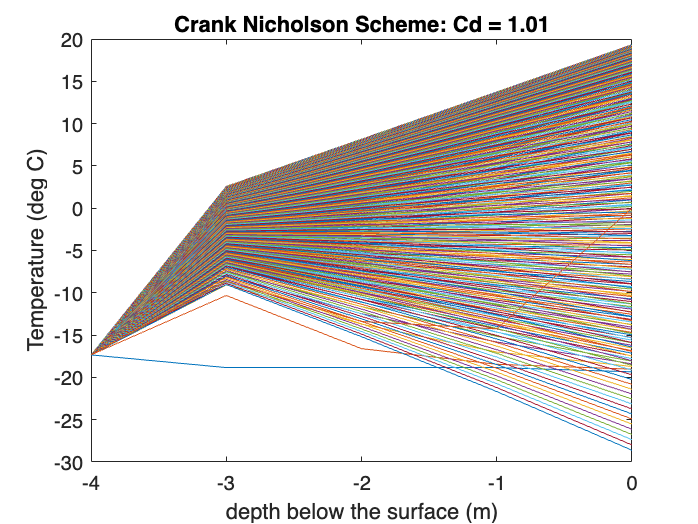

%set surface boundary condition 
for i= 1: nt
    Tbound(1,i)=surftemp(I(i));%neuman boundary aprroximated by cubic spline interpolation of observed data
end 

%set bottom boundary 
Tbound(end, :)= Tbound(1,1)+2; %sufficiently turbid such that it can be assumed to be insulated at bottom 
%set intial condition (T0 for all z)
T(1,:)=Tbound(1,:);  
T(end,1)= Tbound(end,1); 
T(2:end-1,1)= Tbound(1,1)+0.5; %assume polymicitic lake thus little mixing

for i=1:nt-1
%dependant on U2, I, Ta, Tw,C
Ts=surftemp(I(i));
a= 0.02 + 0.01*(0.5-C(i))*(1-sin(pi*(I(i)-81)/183));%parameter that depends on cloud cover an djulian day (13)
deltadeg=-23.4*cos(360*(I(i) + 10)/365);
delta=deg2rad(deltadeg);%solar declination determined by Oke, 1987 (15)
cos_H=-tan(theta)*tan(delta);
H=acos(cos_H);%half-day length (units?) (14)  
b = a + sin(theta)*sin(delta); %(17)
c=cos(theta)*cos(delta);%(18)
B= ((b-c)/(b+c))*tan(pi*H/(2*td))^2; % (19)

if ((b^2) -(c^2)) > 0 %16
    F= 2*(b^2-c^2)^(-1/2)*atan(sqrt(B)); %integration factor 
else 
    F= (-b+c^2)^(-1/2)*log((1+sqrt(-B)/(1-sqrt(-B))));%for b^2-c^2 <0; (16)
end 
As= (a*td/2*H*pi)*F;  %shortwave albedo of the water surface (12)
Ks= Kd(i)*(1-As);%is the net shortwave radiation at the water surface (W/m^2) (11) 

ws= 1.2E-3*U2(i);%w* is the surface value of the friction velocity (m s-) (6)
ks=  6.6*(sin(theta))^(1/2)*U2(i)^-1.84;% a  latitudinally dependent parameter of the Ekman profile, (7) 
Tk = Ts+273;%temperature of surface in kelvin 
rhof= (1-1.9549E-5*abs(Tk-277)^1.68)*10^3; %density of fresh water (kg/m^3)
Nbv= 0.002;%sqrt(-g/(rhof*(dp/dp/dz)));%brunt-vaisala frequency N 

tk= 1-(375.15/(Ts+273));%ambient vapor pressure of the air (27) 
tk2= 1-(375.15/(Tw(i)+273));
e0= 101.325*exp(13.3185*tk -1.9760*tk^2 -0.6445*tk^3 -0.1299*tk^4); % saturation vapor pressure at the lake surface 
eas=101.325*exp(13.3185*tk2 -1.9760*tk2^2 -0.6445*tk2^3 -0.1299*tk2^4);
gamma=(Cp*P(i))/(lambda*Rmw); %psychometric constant (kPa degC ^-1) 
ea = eas - gamma*(Ta(i)-Tw(i)); % ambient vapor pressure of the air

if (1-C(i)) > 0.4 || (1-C(i)) == 0.4
    esp_a= 0.84 - (0.1-9.973E-6*ea)*(1-C(i)) + 3.491E-5*ea; % (21) emissivity of the atmosphere
else 
    esp_a= 0.87 -(0.175 -29.92E-6*ea)*(1-C(i)) + 2.693e-5*ea; %(22)
end 
Ld= esp_a*sig*(Ta(i) +273)^4; % (20) 
Lds= (1-A1)*Ld; %long wave radiation from the atmosphere (23)
Lu= esp*sig*(Ts+273)^3 ;%stefan boltzman law (24) longwave rad from lake surface 
Le=1.91846E6*((Ts +273)/(Ts +329.09))^2; %latent hear fo vaporization (MJ kg^-1) 
E= N*U2(i)*(e0-ea); %evaporation (mm) 
Qe= rhoe*Le*E*(277.7778/1000)*24; %(29) rho is density of the evaporated water vapor (= 1kg m^-3) and Le is the latent heat of vaporization (MJ kg^-1) 
R= gamma*(Ts-Ta(i))*(e0-ea); %bowen ratio R
Qh= R*Qe; % flux of sensible heat (31)

    for m=2:nz
        Ri= (-1 + sqrt(1+ (40*Nbv^2*(k^2)*(z(m)^2))/ ws^2*exp(-2*k*z(m))))/20; %richardson number 
        K(m) = km + eddy_dif(z(m),k,ws,ks,Ri,P0);
        Cd = K(m)*dt/dz^2;
        phi(i)= (1-Beta)*Ks*exp(-n*z(m)); % heat source term in (W/m^2) Beer's Law (2)
        S(m,i) = S(m,i)*phi(i)*(A(m))/dz;
        T(m,i+1) = T(m,i) + Cd*(T(m,i)-T(m-1,i)-2*T(m,i)+T(m-1,i)) + S(m,i);
        T(end,:) = T(end,1);
    end 

end

T_inverted = flipud(T);%invert so that the top is the surface 
figure(1)
% Create the contour plot with the inverted depth axis
contourf(T_inverted)
% Set the depth values as y-axis tick labels
depth_labels = string(z);  % Assuming 'z' contains your depth values
depth_labels = depth_labels(end:-1:1);  % Reverse the order to match inverted T
yticks(1:length(z))  % Set the number of ticks to match the depth values
yticklabels(depth_labels)  % Set the depth values as tick labels
ylabel("depth below the surface (m)")
xlabel("Time (days)")
cb=colorbar;
ylabel(cb, 'Temperature (deg C)')
title("FTCS Scheme")

stability testing for FTCS 

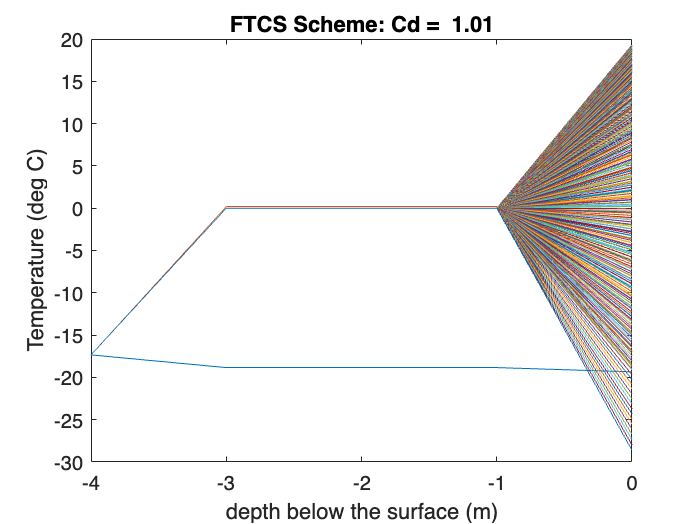

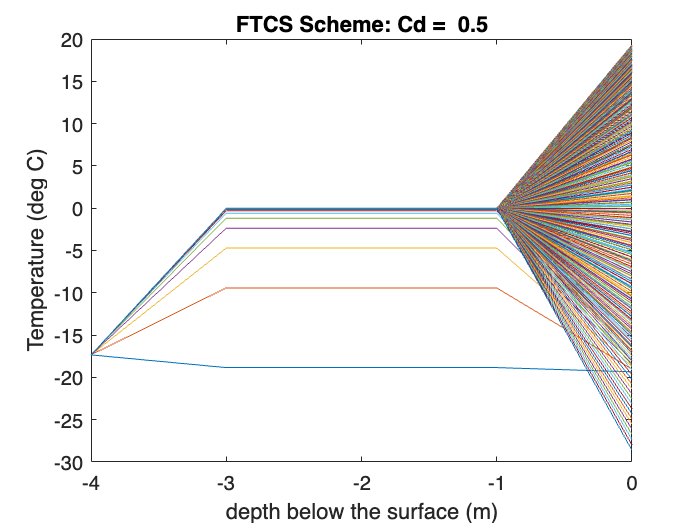

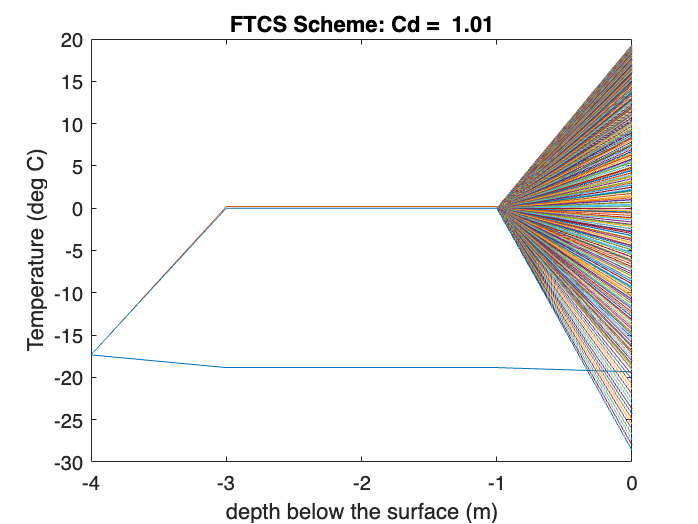

Cds = [0.01,0.5,1.01];
for y = 1:length(Cds)
    A=[323343600, 210124300, 52497200, 6732487, 345632];%area in m^2 for depths 1m-4m 
    %preallocation 
    I=linspace(1,365,365); % julian day 
    t= I; %time in julian days 
    dz = 1;%meters 
    dt = 1; %days 
    
    z=0:dz:4; %depth in meters 
    nt=length(t);
    nz=length(z);
    T=nan.*ones(nz,nt);
    Tbound=nan.*ones(nz-2,nt);
    S=nan.*ones(nz,nt);
    phi = nan.*ones(1,nt);
    K = nan.*ones(nz,1);
    
    %set "source" term 
    for i = 1: width(S)
        S(:,i)= 1./(A*Cw);
    end 
    S(1,1) = 0; 
    S;
    %set surface boundary condition 
    for i= 1: nt
        Tbound(1,i)=surftemp(I(i));%neuman boundary aprroximated by cubic spline interpolation of observed data
    end 
    %set bottom boundary 
    Tbound(end, :)= Tbound(1,1)+2; %sufficiently turbid such that it can be assumed to be insulated at bottom 
    %set intial condition (T0 for all z)
    T(1,:)=Tbound(1,:);  
    T(end,1)= Tbound(end,1); 
    T(2:end-1,1)= Tbound(1,1)+0.5; %assume polymicitic lake thus little mixing
    
    for i=1:nt-1
    %dependant on U2, I, Ta, Tw,C
    Ts=surftemp(I(i));
    a= 0.02 + 0.01*(0.5-C(i))*(1-sin(pi*(I(i)-81)/183));%parameter that depends on cloud cover an djulian day (13)
    deltadeg=-23.4*cos(360*(I(i) + 10)/365);
    delta=deg2rad(deltadeg);%solar declination determined by Oke, 1987 (15)
    cos_H=-tan(theta)*tan(delta);
    H=acos(cos_H);%half-day length (units?) (14)  
    b = a + sin(theta)*sin(delta); %(17)
    c=cos(theta)*cos(delta);%(18)
    B= ((b-c)/(b+c))*tan(pi*H/(2*td))^2; % (19)
    
    if ((b^2) -(c^2)) > 0 %16
        F= 2*(b^2-c^2)^(-1/2)*atan(sqrt(B)); %integration factor 
    else 
        F= (-b+c^2)^(-1/2)*log((1+sqrt(-B)/(1-sqrt(-B))));%for b^2-c^2 <0; (16)
    end 
    As= (a*td/2*H*pi)*F;  %shortwave albedo of the water surface (12)
    Ks= Kd(i)*(1-As);%is the net shortwave radiation at the water surface (W/m^2) (11) 
    
    ws= 1.2E-3*U2(i);%w* is the surface value of the friction velocity (m s-) (6)
    ks=  6.6*(sin(theta))^(1/2)*U2(i)^-1.84;% a  latitudinally dependent parameter of the Ekman profile, (7) 
    Tk = Ts+273;%temperature of surface in kelvin 
    rhof= (1-1.9549E-5*abs(Tk-277)^1.68)*10^3; %density of fresh water (kg/m^3)
    Nbv= 0.002;%sqrt(-g/(rhof*(dp/dp/dz)));%brunt-vaisala frequency N 
    
    tk= 1-(375.15/(Ts+273));%ambient vapor pressure of the air (27) 
    tk2= 1-(375.15/(Tw(i)+273));
    e0= 101.325*exp(13.3185*tk -1.9760*tk^2 -0.6445*tk^3 -0.1299*tk^4); % saturation vapor pressure at the lake surface 
    eas=101.325*exp(13.3185*tk2 -1.9760*tk2^2 -0.6445*tk2^3 -0.1299*tk2^4);
    gamma=(Cp*P(i))/(lambda*Rmw); %psychometric constant (kPa degC ^-1) 
    ea = eas - gamma*(Ta(i)-Tw(i)); % ambient vapor pressure of the air
    
    if (1-C(i)) > 0.4 || (1-C(i)) == 0.4
        esp_a= 0.84 - (0.1-9.973E-6*ea)*(1-C(i)) + 3.491E-5*ea; % (21) emissivity of the atmosphere
    else 
        esp_a= 0.87 -(0.175 -29.92E-6*ea)*(1-C(i)) + 2.693e-5*ea; %(22)
    end 
    Ld= esp_a*sig*(Ta(i) +273)^4; % (20) 
    Lds= (1-A1)*Ld; %long wave radiation from the atmosphere (23)
    Lu= esp*sig*(Ts+273)^3 ;%stefan boltzman law (24) longwave rad from lake surface 
    Le=1.91846E6*((Ts +273)/(Ts +329.09))^2; %latent hear fo vaporization (MJ kg^-1) 
    E= N*U2(i)*(e0-ea); %evaporation (mm) 
    Qe= rhoe*Le*E*(277.7778/1000)*24; %(29) rho is density of the evaporated water vapor (= 1kg m^-3) and Le is the latent heat of vaporization (MJ kg^-1) 
    R= gamma*(Ts-Ta(i))*(e0-ea); %bowen ratio R
    Qh= R*Qe; % flux of sensible heat (31)
    

    for m=2:nz
        Ri= (-1 + sqrt(1+ (40*Nbv^2*(k^2)*(z(m)^2))/ ws^2*exp(-2*k*z(m))))/20; %richardson number 
        K(m) = km + eddy_dif(z(m),k,ws,ks,Ri,P0);
        Cd = Cds(y); %K(m)*dt/dz^2;
        phi(i)= (1-Beta)*Ks*exp(-n*z(m)); % heat source term in (W/m^2) Beer's Law (2)
        S(m,i) = S(m,i)*phi(i)*((A(m-1)-A(m))/dz);
        T(m,i+1) = T(m,i) + Cd*(T(m,i)-T(m-1,i)-2*T(m,i)+T(m-1,i)) + S(m,i);
        T(end,:) = T(end,1);
    end 
    
    
    end
    figure()
    plot(-z,T)
    title("FTCS Scheme: Cd =  " + string(Cd))
    xlabel("depth below the surface (m)")
    ylabel("Temperature (deg C)")
end

Numerical Method: Crank Nic

centered difference in time 

Centered difference in space 

Time scale: 1 year (2022-2023)

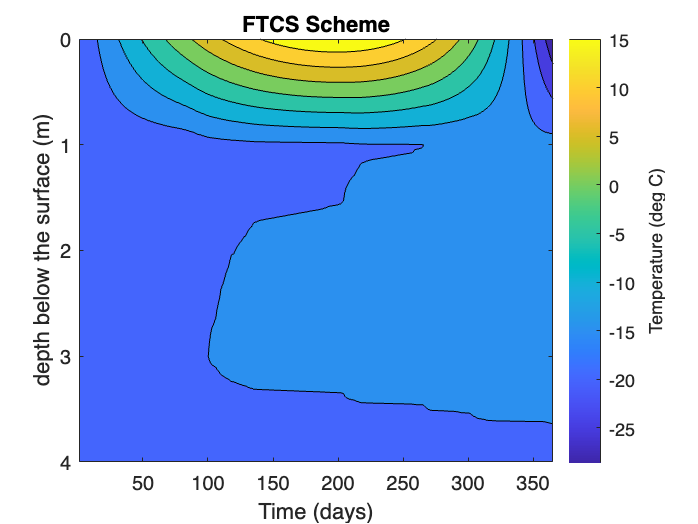


%preallocation 
I=linspace(1,365,365); % julian day 
t= I; %time in julian days 
nt= 365;
dz=1;
D=.01;
dt=1;
Cd= D*dt/dz^2; 
z=0:1:4;
nz=length(z);
T=nan.*ones(nz,nt+1);
Tbound = zeros(nz-2, nt+1);
nt=length(t);
S=nan.*ones(nz,nt);
phi = nan.*ones(1,nt);
K = nan.*ones(nz,1);
%Parameters needed to solve the equation within the Crank-Nicholson method

%set "source" term 
for i = 1: width(S)
    S(:,i)= 1./(A*Cw);
end 
S(1,1) = 0; 
S;
%set surface boundary condition 
for i= 1: nt
    Tbound(1,i)=surftemp(I(i));%neuman boundary aprroximated by cubic spline interpolation of observed data
end 

%set bottom boundary 
Tbound(end, :)= Tbound(1,1)+2; %sufficiently turbid such that it can be assumed to be insulated at bottom 
%set intial condition (T0 for all z)
T(1,:)=Tbound(1,:);  
T(end,1)= Tbound(end,1); 
T(2:end-1,1)= Tbound(1,1)+0.5; %assume polymicitic lake thus little mixing


%Set boundary conditions
Tbound(end,:)=-3; %deg C
% sets surface layer to be function of time for boundary and initial
% conditions
for i =1:nt
    t(i)=(i-1)*dt;
    Tbound(1,i)=surftemp(I(i));
    T(1,i)=surftemp(I(i));
end
%set inital conditions for T
T(end, :)=T(1,1)+2;%z at 4 = 11 
T(2:end-1,1)=T(1,1)+0.5;%assume 10 everywhere else for t0
T;
% define M_right (MR) and M_left (ML) tridiagonal CN method
aal(1:nz-3)=-Cd/2;
bbl(1:nz-2)=1+Cd;
ccl(1:nz-3)=-Cd/2;
ML= diag(bbl,0) +diag(aal, -1) + diag(ccl,1);
aar(1:nz-3)=Cd/2;
bbr(1:nz-2)=1.-Cd;
ccr(1:nz-3)=Cd/2;
MR= diag(bbr,0) +diag(aar, -1) + diag(ccr,1);

for j = 1:nz
    Ri= (-1 + sqrt(1+ (40*Nbv^2*(k^2)*(z(m)^2))/ ws^2*exp(-2*k*z(m))))/20; %richardson number 
    K(m) = km + eddy_dif(z(m),k,ws,ks,Ri,P0);
    phi(i)= (1-Beta)*Ks*exp(-n*z(m)); % heat source term in (W/m^2) Beer's Law (2)
    S(m,i) = S(m,i)*phi(i)*((A(m-1)-A(m))/dz);
end 
%multiply ML inverse and MR
%implement CN
for k=1:nt
    T(2:nz-1, k+1) = inv(ML) * (MR*T(2:nz-1,k) + 0.5*Cd*Tbound(:,k) + 0.5*Cd*Tbound(:,k+1))+S(2:nz-1,k);
end

T_inverted = flipud(T);%invert so that the top is the surface 
figure()
% Create the contour plot with the inverted depth axis
contourf(T_inverted)
% Set the depth values as y-axis tick labels
depth_labels = string(z);  % Assuming 'z' contains your depth values
depth_labels = depth_labels(end:-1:1);  % Reverse the order to match inverted T
yticks(1:length(z))  % Set the number of ticks to match the depth values
yticklabels(depth_labels)  % Set the depth values as tick labels
ylabel("depth below the surface (m)")
xlabel("Time (days)")
cb=colorbar;
ylabel(cb, 'Temperature (deg C)')
title("Crank Nicholson Scheme")

stability testing for crank nicolson  

Ri = 0

Ri = 0

Ri = 0

Ri = 0

Ri = 0

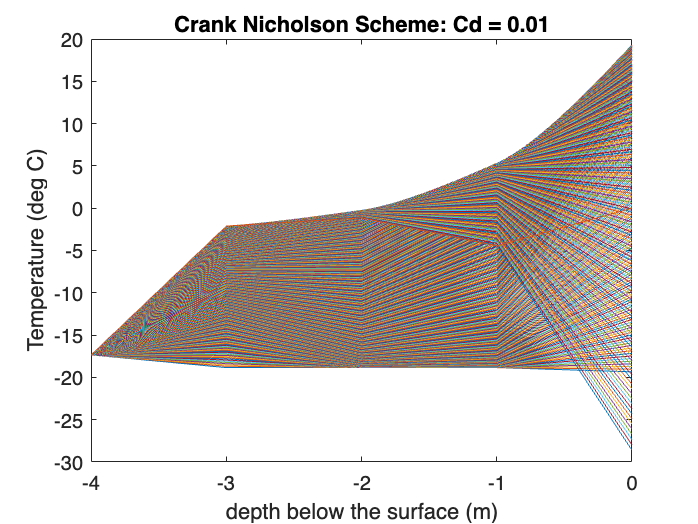

Ri = 0

Ri = 0

Ri = 0

Ri = 0

Ri = 0

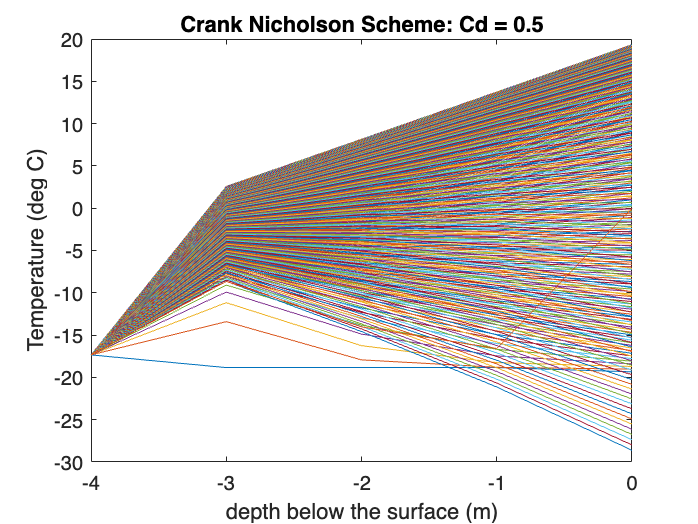

Ri = 0

Ri = 0

Ri = 0

Ri = 0

Ri = 0

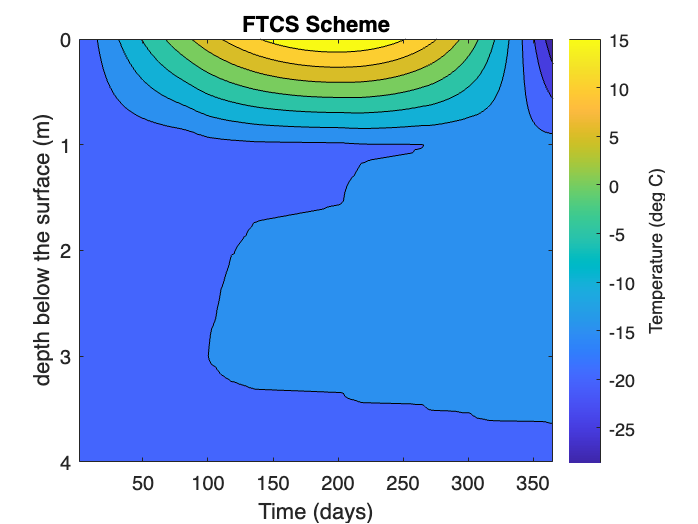

Cds = [0.01,0.5,1.01];
for y = 1:length(Cds)   
    %preallocation 
    I=linspace(1,365,365); % julian day 
    t= I; %time in julian days 
    nt= 365;
    dz=1;
    D=Cds(y);
    dt=1;
    Cd= D*dt/dz^2; 
    z=0:1:4;
    nz=length(z);
    T=nan.*ones(nz,nt+1);
    Tbound = zeros(nz-2, nt+1);
    nt=length(t);
    S=nan.*ones(nz,nt);
    phi = nan.*ones(1,nt);
    K = nan.*ones(nz,1);
    %Parameters needed to solve the equation within the Crank-Nicholson method
    
    
    %set "source" term 
    for i = 1: width(S)
        S(:,i)= 1./(A*Cw);
    end 
    S(1,1) = 0; 
    S;
    %set surface boundary condition 
    for i= 1: nt
        Tbound(1,i)=surftemp(I(i));%neuman boundary aprroximated by cubic spline interpolation of observed data
    end 
    
    %set bottom boundary 
    Tbound(end, :)= Tbound(1,1)+2; %sufficiently turbid such that it can be assumed to be insulated at bottom 
    %set intial condition (T0 for all z)
    T(1,:)=Tbound(1,:);  
    T(end,1)= Tbound(end,1); 
    T(2:end-1,1)= Tbound(1,1)+0.5; %assume polymicitic lake thus little mixing
    
    
    %Set boundary conditions
    Tbound(end,:)=-3; %deg C
    % sets surface layer to be function of time for boundary and initial
    % conditions
    for i =1:nt
        t(i)=(i-1)*dt;
        Tbound(1,i)=surftemp(I(i));
        T(1,i)=surftemp(I(i));
    end
    %set inital conditions for T
    T(end, :)=T(1,1)+2;%z at 4 = 11 
    T(2:end-1,1)=T(1,1)+0.5;%assume 10 everywhere else for t0
    T;
    % define M_right (MR) and M_left (ML) tridiagonal CN method
    aal(1:nz-3)=-Cd/2;
    bbl(1:nz-2)=1+Cd;
    ccl(1:nz-3)=-Cd/2;
    ML= diag(bbl,0) +diag(aal, -1) + diag(ccl,1);
    aar(1:nz-3)=Cd/2;
    bbr(1:nz-2)=1.-Cd;
    ccr(1:nz-3)=Cd/2;
    MR= diag(bbr,0) +diag(aar, -1) + diag(ccr,1);
    %multiply ML inverse and MR

    for j = 1:nz
    Ri= (-1 + sqrt(1+ (40*Nbv^2*(k^2)*(z(m)^2))/ ws^2*exp(-2*k*z(m))))/20; %richardson number 
    K(m) = km + eddy_dif(z(m),k,ws,ks,Ri,P0);
    phi(i)= (1-Beta)*Ks*exp(-n*z(m)); % heat source term in (W/m^2) Beer's Law (2)
    S(m,i) = S(m,i)*phi(i)*((A(m-1)-A(m))/dz);
    end 

    %implement CN
    for k=1:nt
        T(2:nz-1, k+1) = inv(ML) * (MR*T(2:nz-1,k) + 0.5*Cd*Tbound(:,k) + 0.5*Cd*Tbound(:,k+1))+S(2:nz-1,k);
    end

    figure ()
    plot(-z,T)
    title("Crank Nicholson Scheme: Cd = " + string(Cd))
    xlabel("depth below the surface (m)")
    ylabel("Temperature (deg C)")
end 

function K=eddy_dif(z,k,ws,ks,Ri,P0)%(m^2*d^-1)
    K= (k*ws*z/P0)*exp(-ks*z)*(1+ 37*Ri^2)^-1; 
end 
function Ts= surftemp(I)
 Ts = -2E-06*I^3 - 0.0002*I^2 + 0.3149*I - 19.655; %cubic spline interpolation 
end 
